oldparam = sympref('HeavisideAtOrigin',1);

# Laplace Transform

part one

syms t
f1 = t*heaviside(t-1);
f2 = sin(t)*exp(-4*t) * heaviside(t);
f3 = 2*t*cos (3*t)*heaviside(t);
laplace(f1)

$$ans = \frac{{\mathrm{e}}^{-s}}{s}+\frac{{\mathrm{e}}^{-s}}{s^{2}}$$

laplace(f2)

$$ans = \frac{1}{{\left(s+4\right)}^{2}+1}$$

laplace(f3)

$$ans = \frac{4\,s^{2}}{{\left(s^{2}+9\right)}^{2}}-\frac{2}{s^{2}+9}$$

part two

syms s
F1 = (1/(s*(s+1)))*exp(-3*s);
F2 = 4/(s*(s^2 +4));
F3 = 1/(s^2 + 3 * s + 1);
ilaplace(F1)

$$ans = -\mathrm{heaviside}\left(t-3\right)\,\left({\mathrm{e}}^{3-t}-1\right)$$

ilaplace(F2)

$$ans = 1-\cos\left(2\,t\right)$$

ilaplace(F3)

$$ans = \frac{2\,\sqrt{5}\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\sinh\left(\frac{\sqrt{5}\,t}{2}\right)}{5}$$

part three

G =(8)/(s^2 +s + 4)

$$G = \frac{8}{s^{2}+s+4}$$

delta_res = ilaplace(G)

$$delta\_res = \frac{16\,\sqrt{15}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)}{15}$$

step_res = ilaplace(G*(1/s))

$$step\_res = 2-2\,{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{15}\,t}{2}\right)+\frac{\sqrt{15}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)}{15}\right)$$

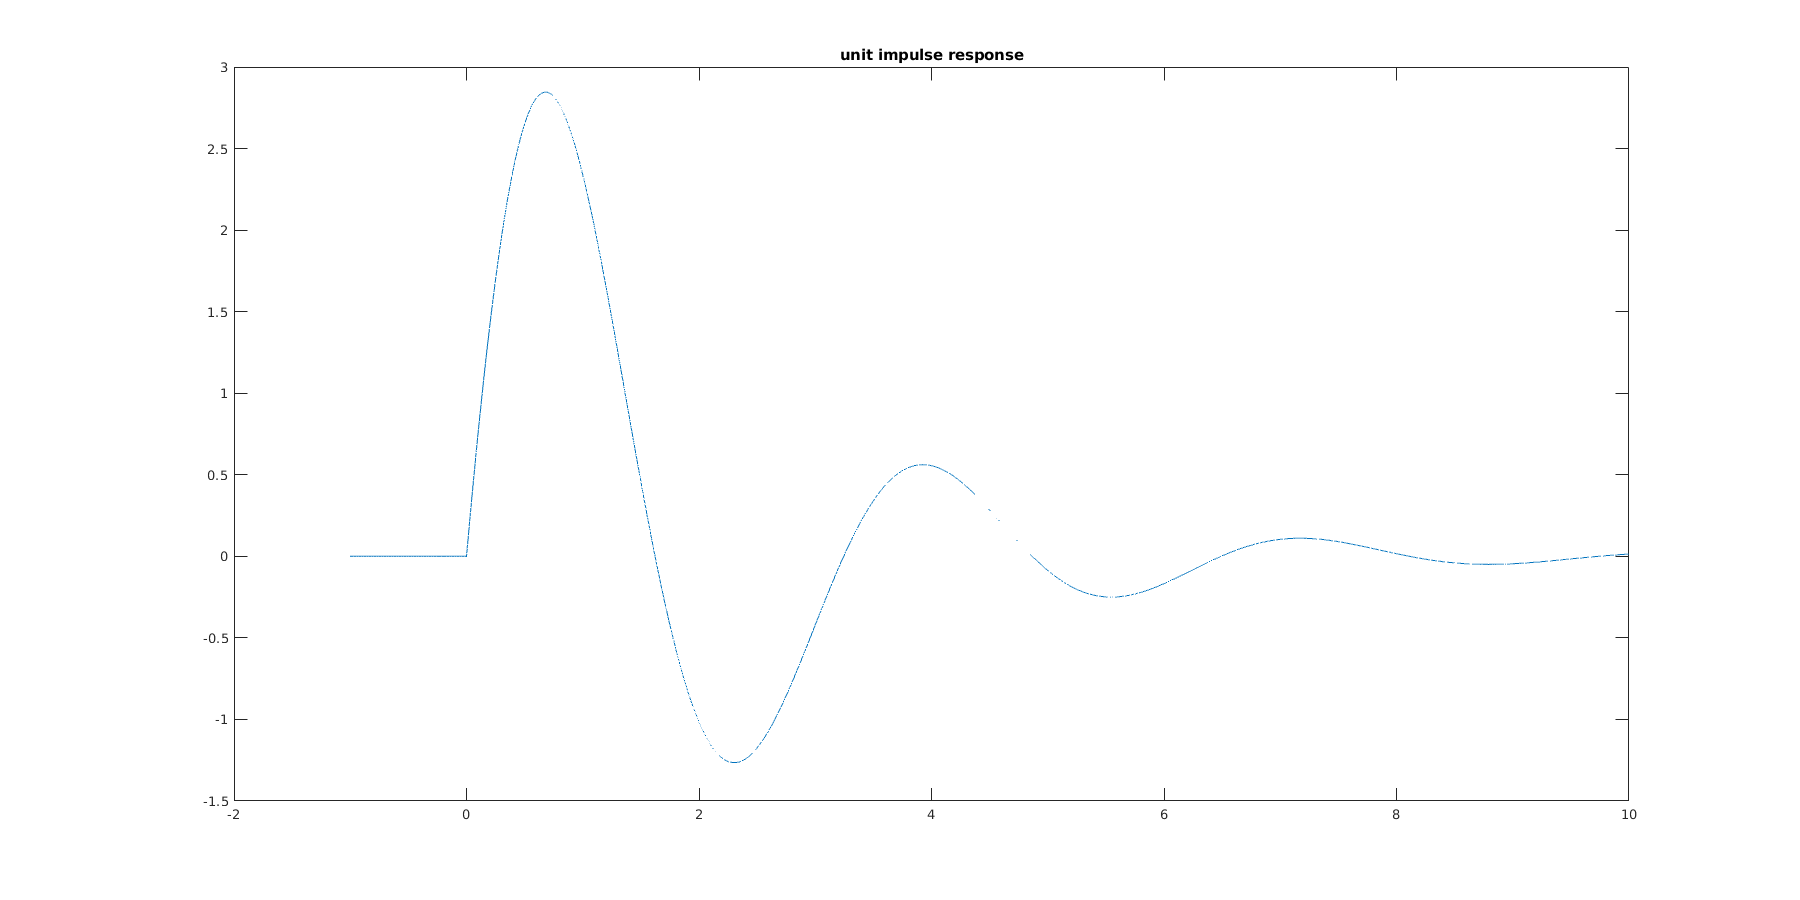

t = -1:0.001:10;
y2 = subs(delta_res,t) .* (t>=0);
plot_fig(t,y2,"unit impulse response")


t = -1:0.001:10;
y2 = subs(step_res,t) .* (t>=0);
figure;
plot_fig(t,y2,"step response");
H = tf([8],[1,1,4])

H =
 
       8
  -----------
  s^2 + s + 4
 
Continuous-time transfer function.



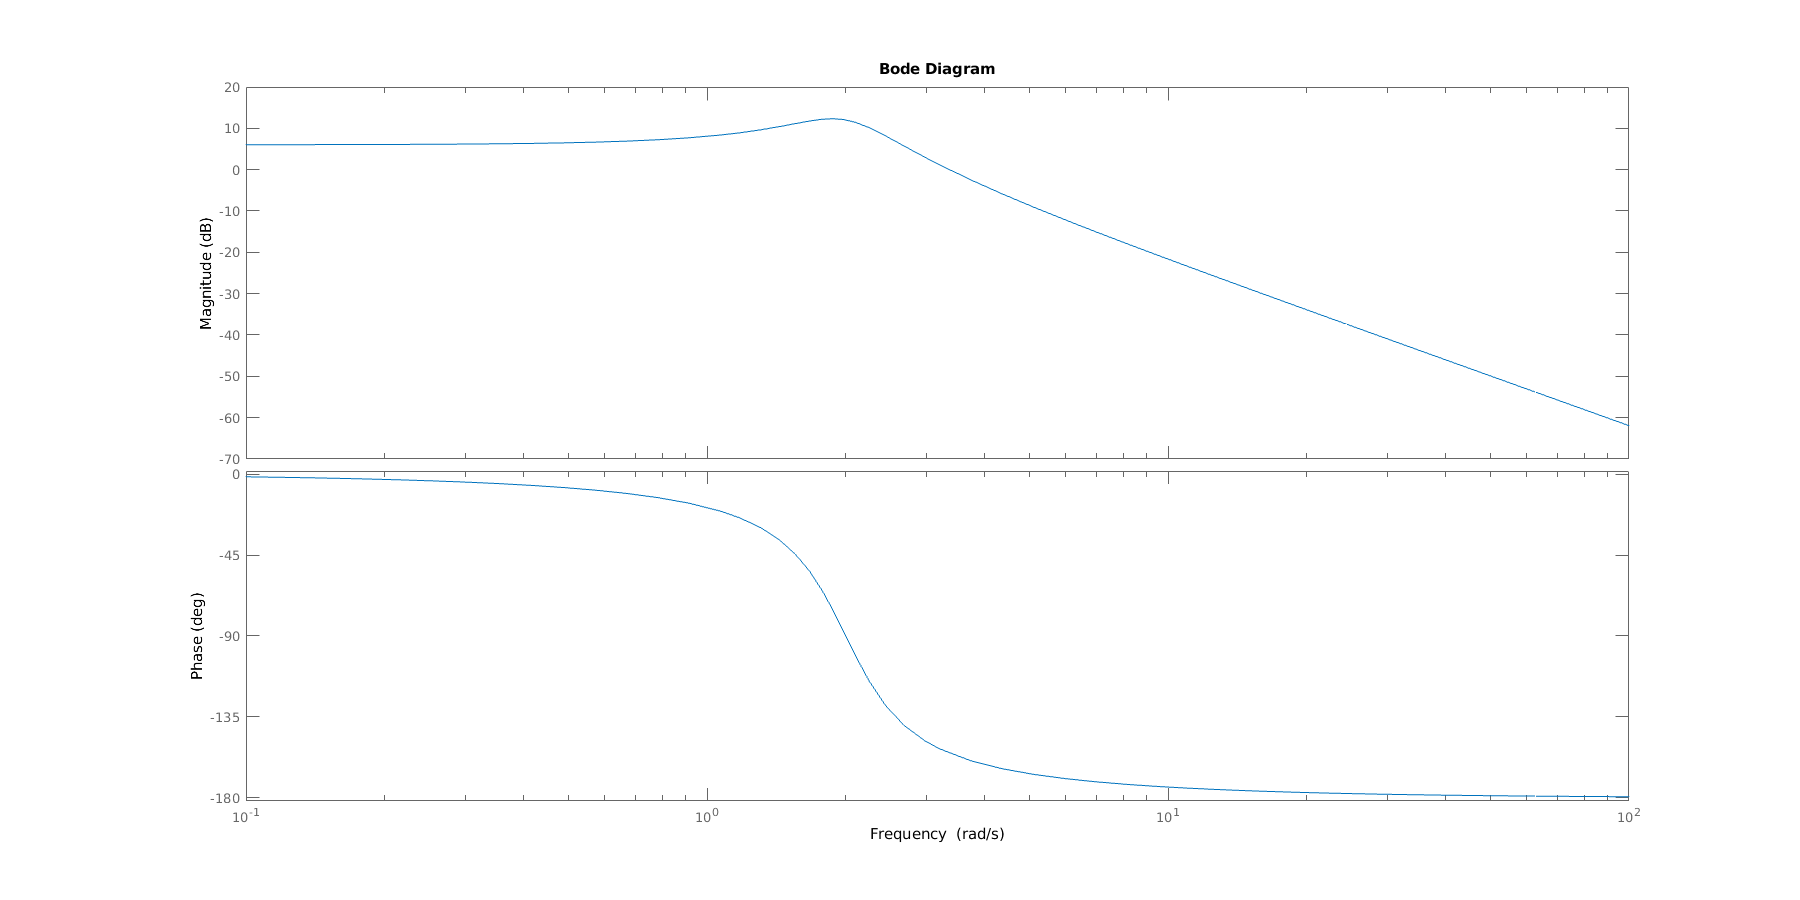

set(gcf,'position',[0,0,1800,900]);
bode(H)

part four

a = 4

G =(2*s+1)/(s^2 + 4*s + 7)

$$G = \frac{2\,s+1}{s^{2}+4\,s+7}$$

step_res = ilaplace(G*(1/s))

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-2\,t}\,\left(\cos\left(\sqrt{3}\,t\right)-4\,\sqrt{3}\,\sin\left(\sqrt{3}\,t\right)\right)}{7}$$

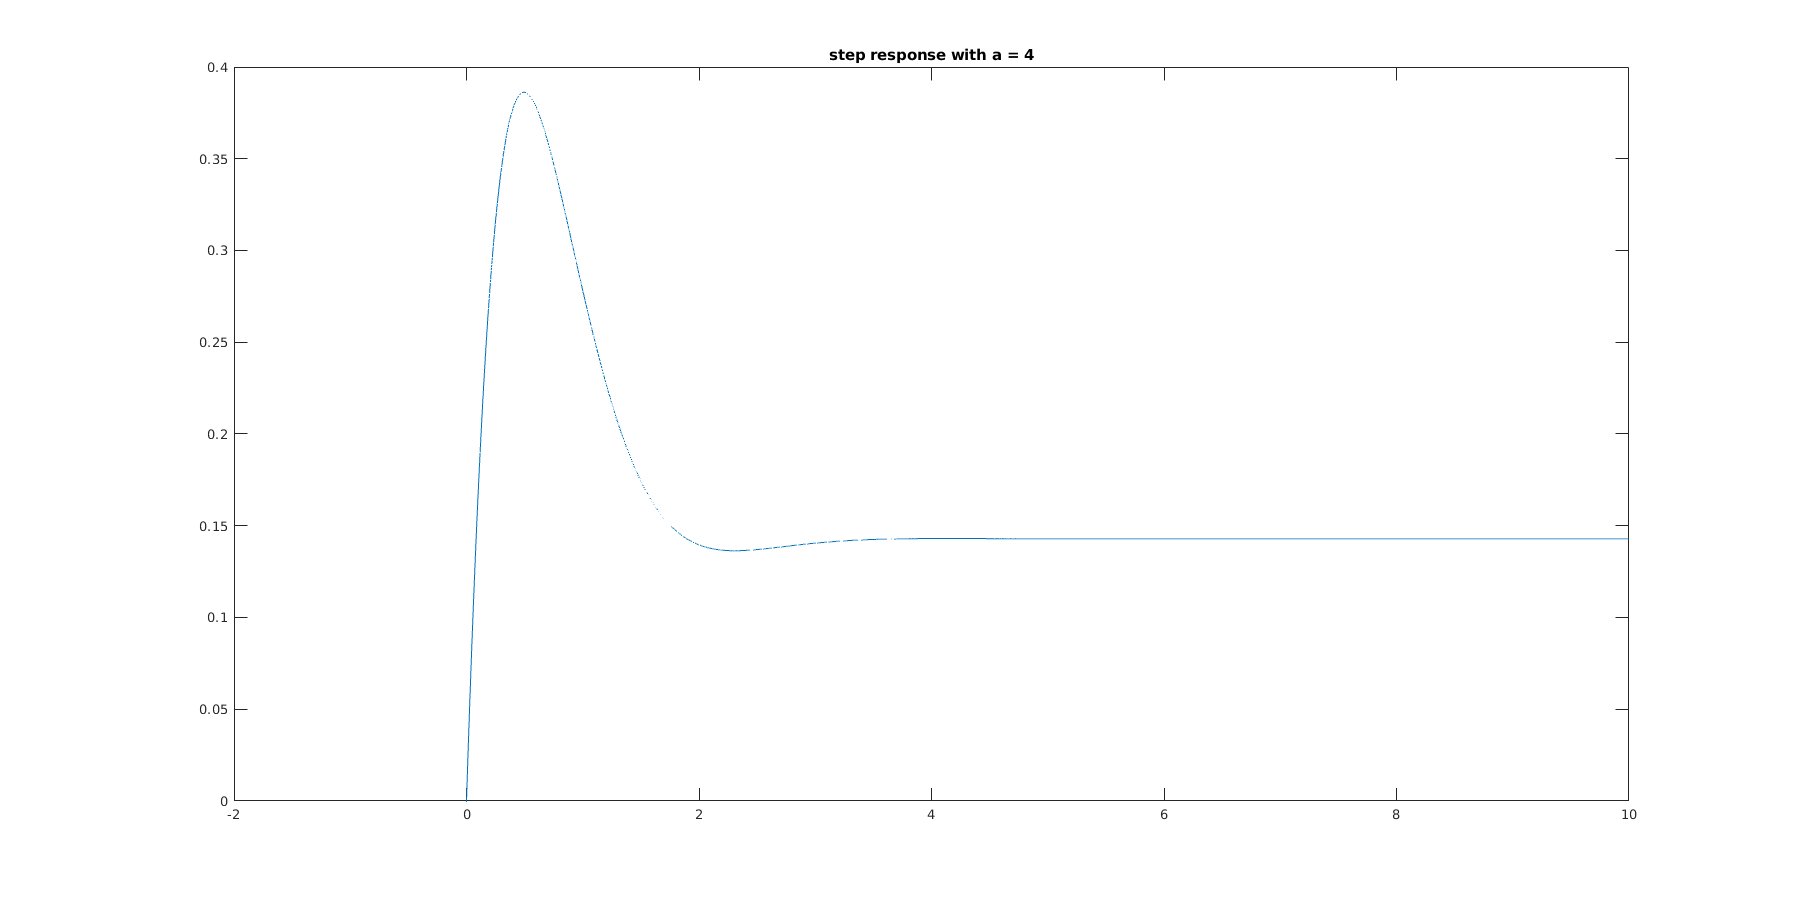

t = -1:0.001:10;
y2 = subs(step_res,t) .* (t>=0);
plot_fig(t,y2,"step response with a = 4")

clear t
syms t
step_res =  sym(1/7) - (exp((-2*t))*(cos(sqrt(sym(3))*t) - 4*sqrt(sym(3))*sin(sqrt(sym(3))*t)))/7

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-2\,t}\,\left(\cos\left(\sqrt{3}\,t\right)-4\,\sqrt{3}\,\sin\left(\sqrt{3}\,t\right)\right)}{7}$$

limit(step_res,t,Inf)

$$ans = \frac{1}{7}$$

t= 0:0.001:2;
y = subs(step_res,t) .* (t>=0);
[val,index] = max(y);
fprintf("maximum at : %f \n with value : %f ",t(index),double(val))

maximum at : 0.495000 
 with value : 0.386194 

a = 6

G =(2*s+1)/(s^2 + 6*s + 7)

$$G = \frac{2\,s+1}{s^{2}+6\,s+7}$$

step_res = ilaplace(G*(1/s))

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-3\,t}\,\left(\cosh\left(\sqrt{2}\,t\right)-\frac{11\,\sqrt{2}\,\sinh\left(\sqrt{2}\,t\right)}{2}\right)}{7}$$

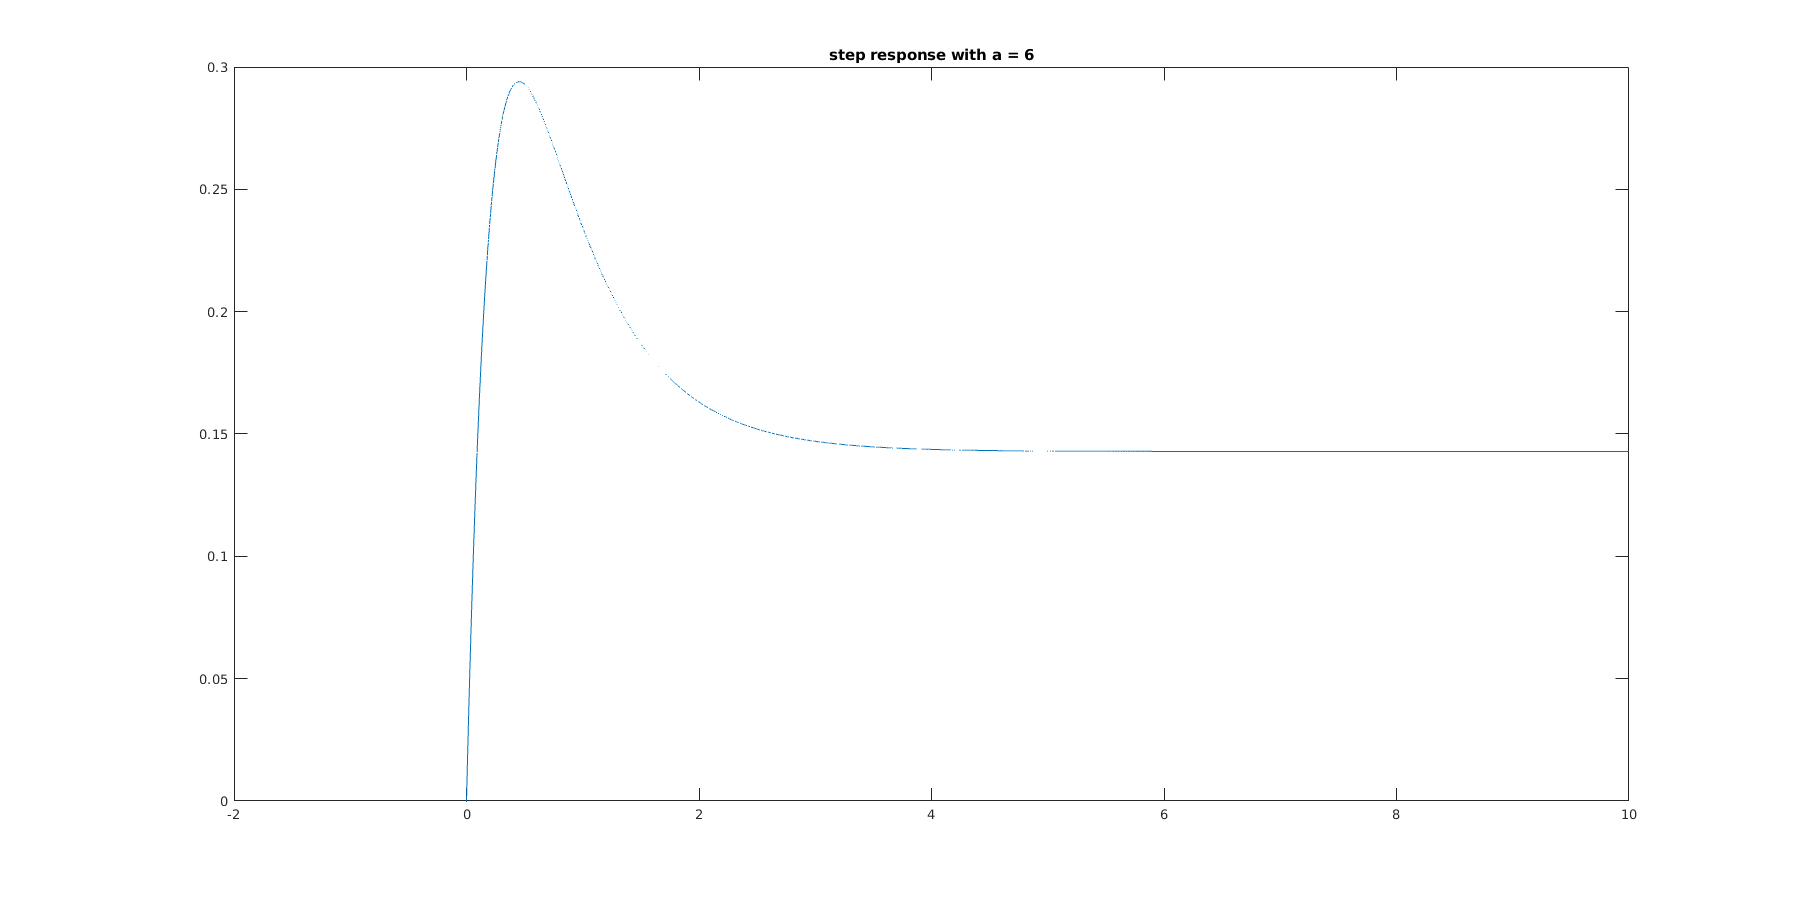

t = -1:0.001:10;
y2 = subs(step_res,t) .* (t>=0);
plot_fig(t,y2,"step response with a = 6")

clear t
syms t
step_res =  sym(step_res)

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-3\,t}\,\left(\cosh\left(\sqrt{2}\,t\right)-\frac{11\,\sqrt{2}\,\sinh\left(\sqrt{2}\,t\right)}{2}\right)}{7}$$

limit(step_res,t,Inf)

$$ans = \frac{1}{7}$$

t= 0:0.001:2;
y = subs(step_res,t) .* (t>=0);
[val,index] = max(y);
fprintf("maximum at : %f \n with value : %f ",t(index),double(val))

maximum at : 0.453000 
 with value : 0.294020 

# Z transform

part one

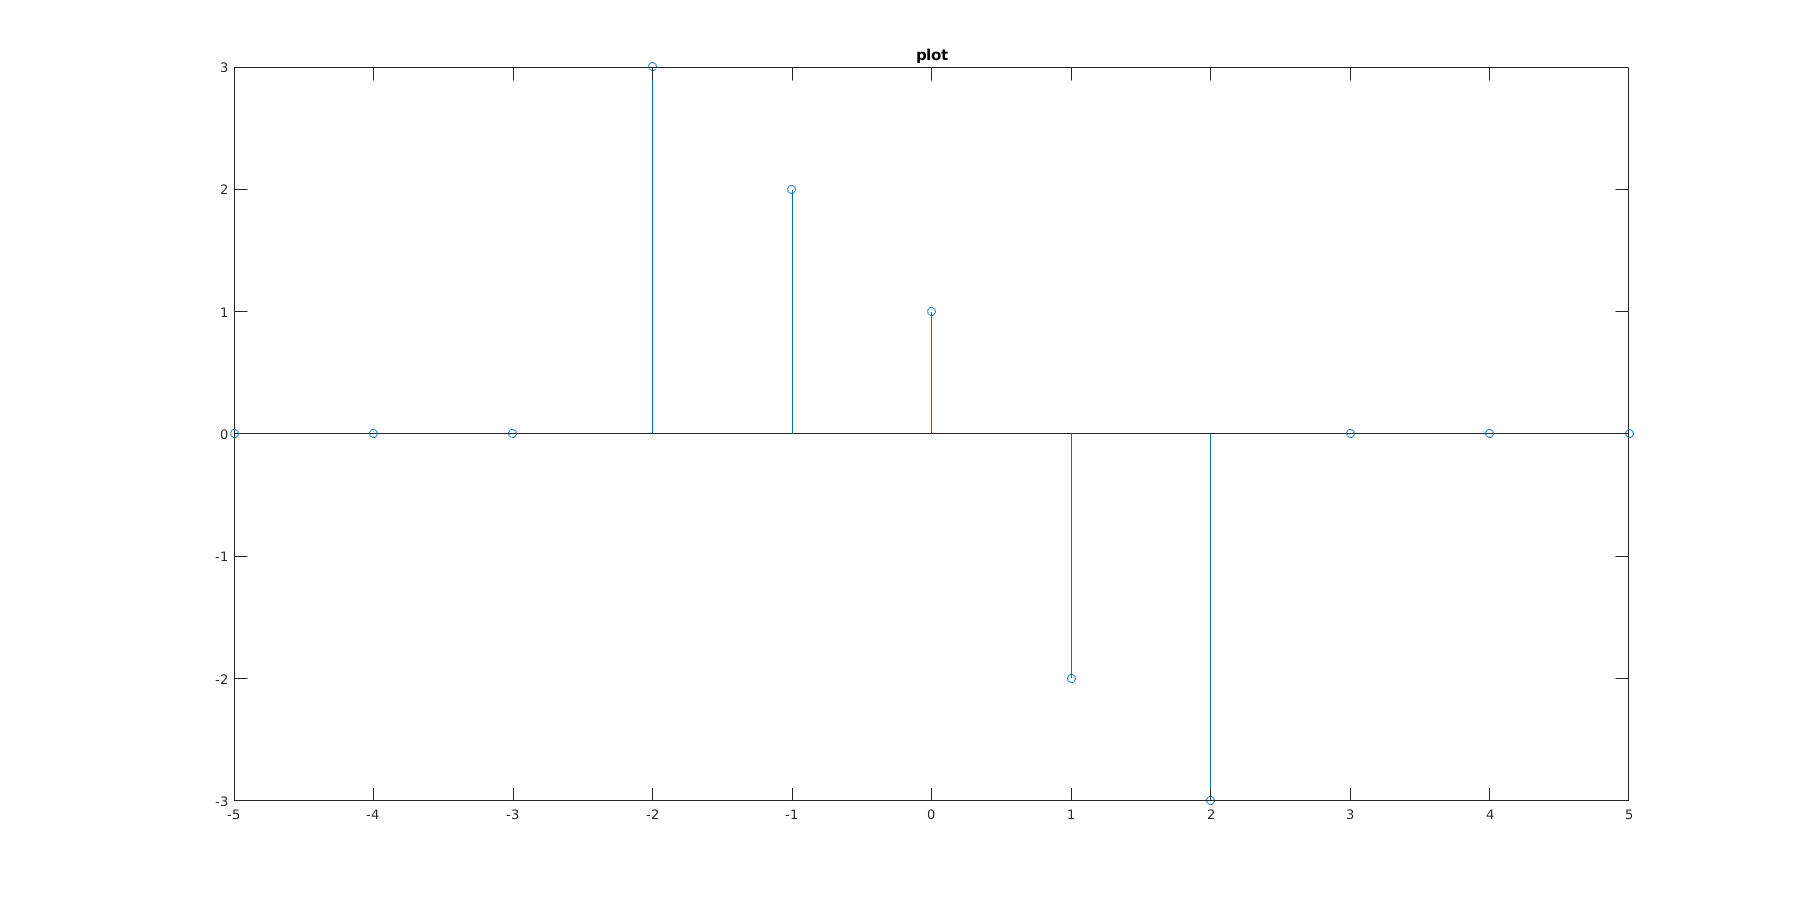

syms n
x1 = (heaviside(n+2)-heaviside(n-1))*(-n+1)-(heaviside(n-1) - heaviside(n-3))*(n+1);
t1 = -5:5;
step_fig(t1,subs(x1,t1),"plot");

x1 = (heaviside(n)-heaviside(n-3))*(-n+3)+(heaviside(n-3) - heaviside(n-5))*(-n+1)

$$x1 = \left(\mathrm{heaviside}\left(n-3\right)-\mathrm{heaviside}\left(n\right)\right)\,\left(n-3\right)-\left(\mathrm{heaviside}\left(n-3\right)-\mathrm{heaviside}\left(n-5\right)\right)\,\left(n-1\right)$$

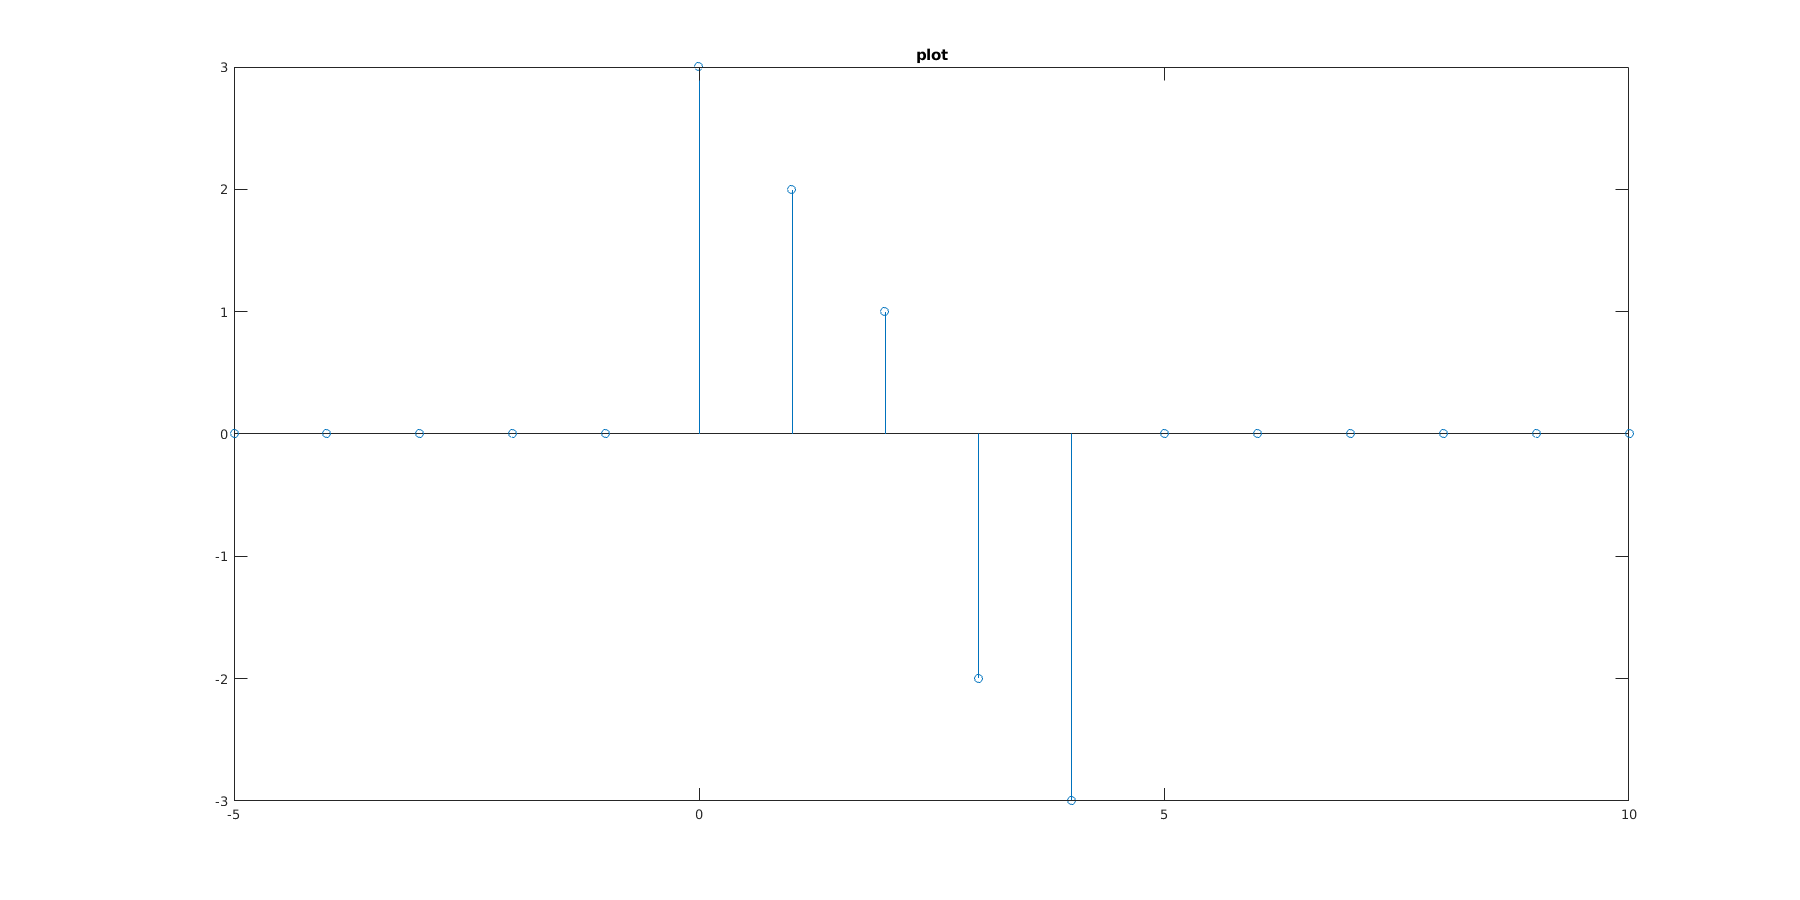

t1 = -5:10;
step_fig(t1,subs(x1,t1),"plot");

syms z
H = simplify(z^{2} * ztrans(x1))% + 2*z^{-1}+3

$$H = \frac{3\,z^{4}+2\,z^{3}+z^{2}-2\,z-3}{z^{2}}$$

H = simplify((3*z^2 + 2*z + 1-2*z^{-1}-3*z^{-2})/(z^2))

$$H = \frac{3\,z^{4}+2\,z^{3}+z^{2}-2\,z-3}{z^{4}}$$

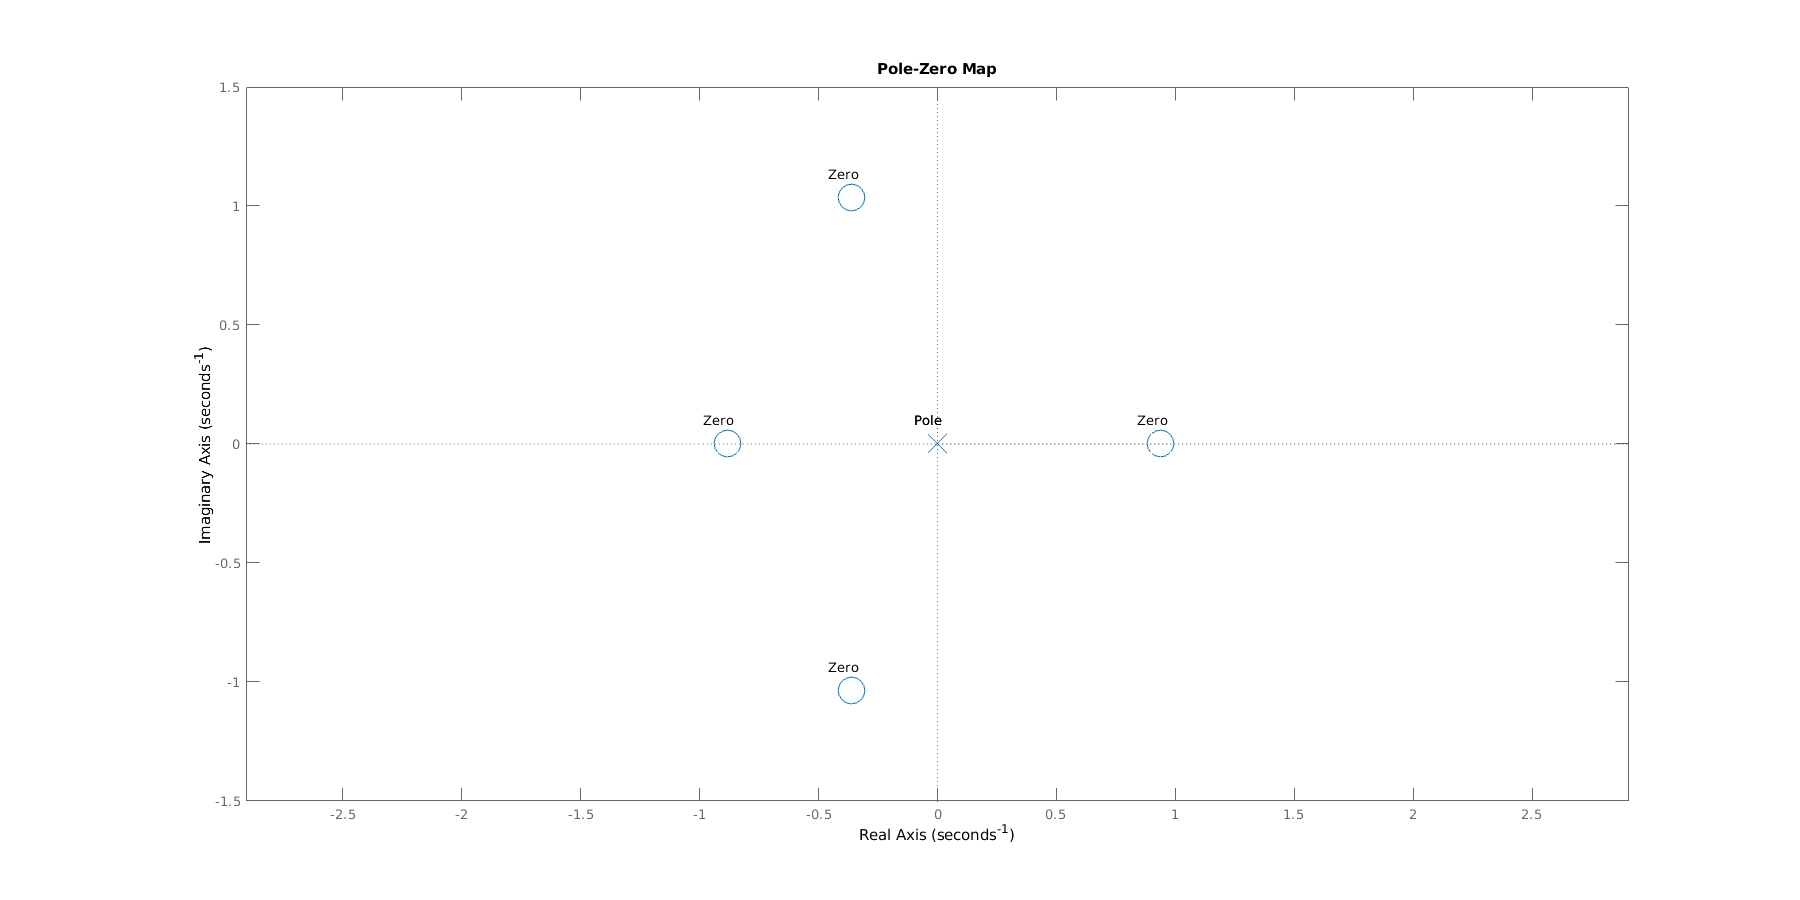

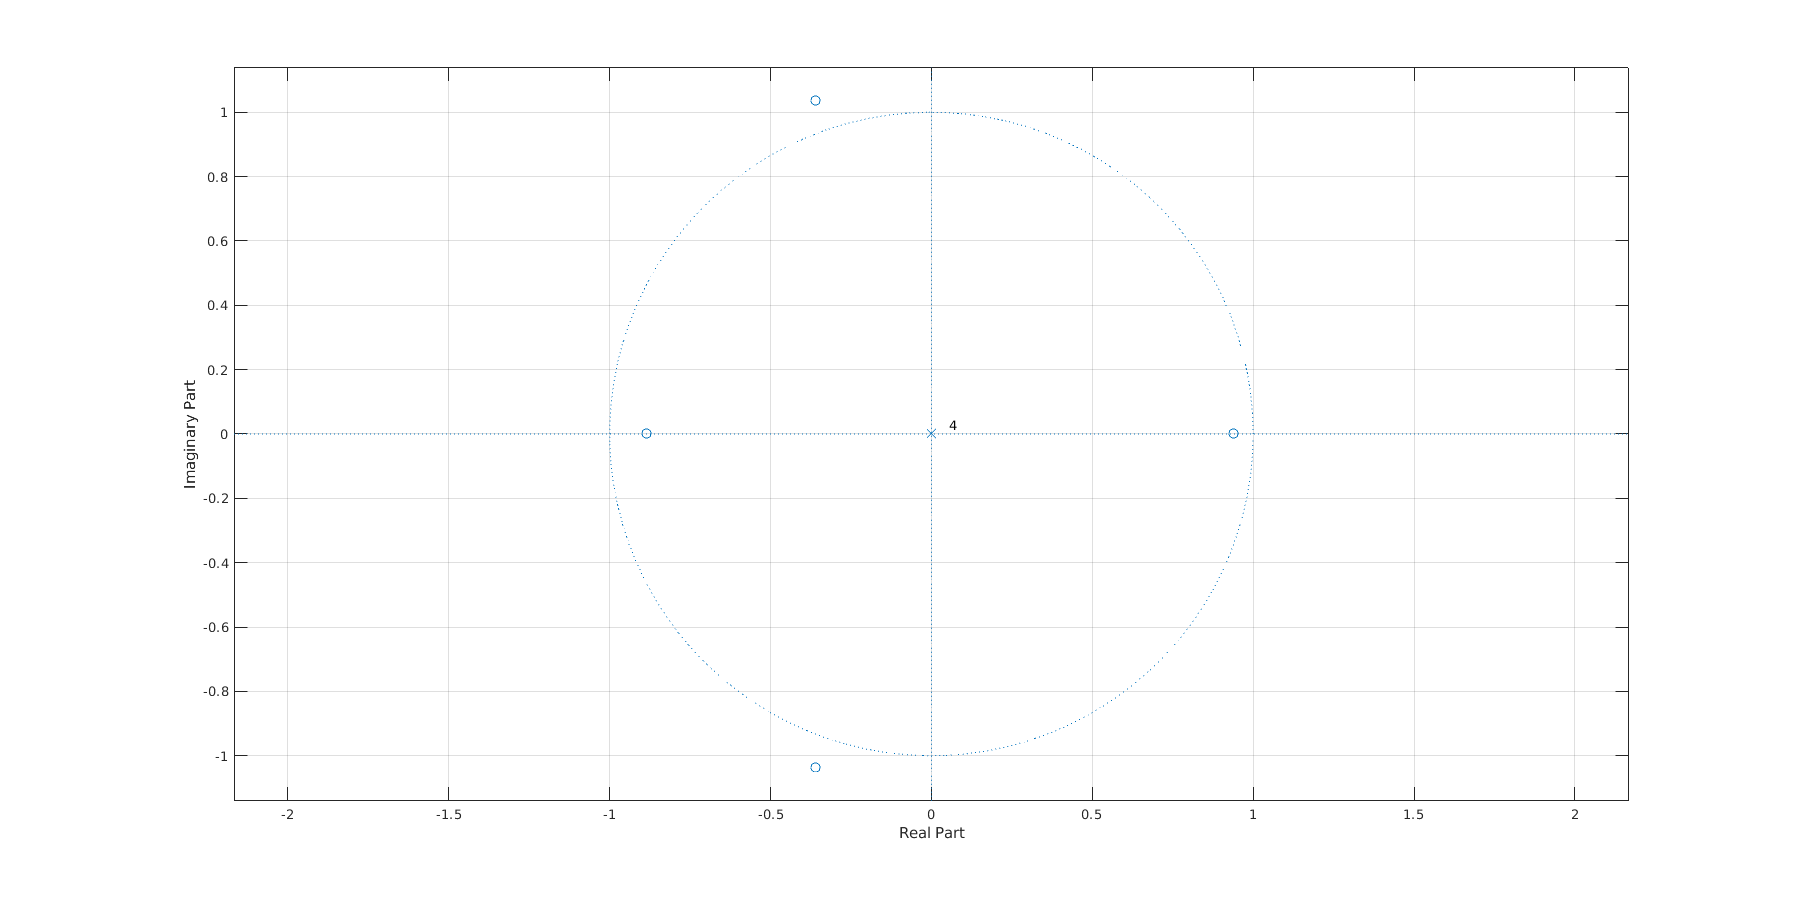

plot_z_plan([3,2,1,-2,-3],[1,0,0])

x2 = 0.8^n * heaviside(n-2)

$$x2 = {\left(\frac{4}{5}\right)}^{n}\,\mathrm{heaviside}\left(n-2\right)$$

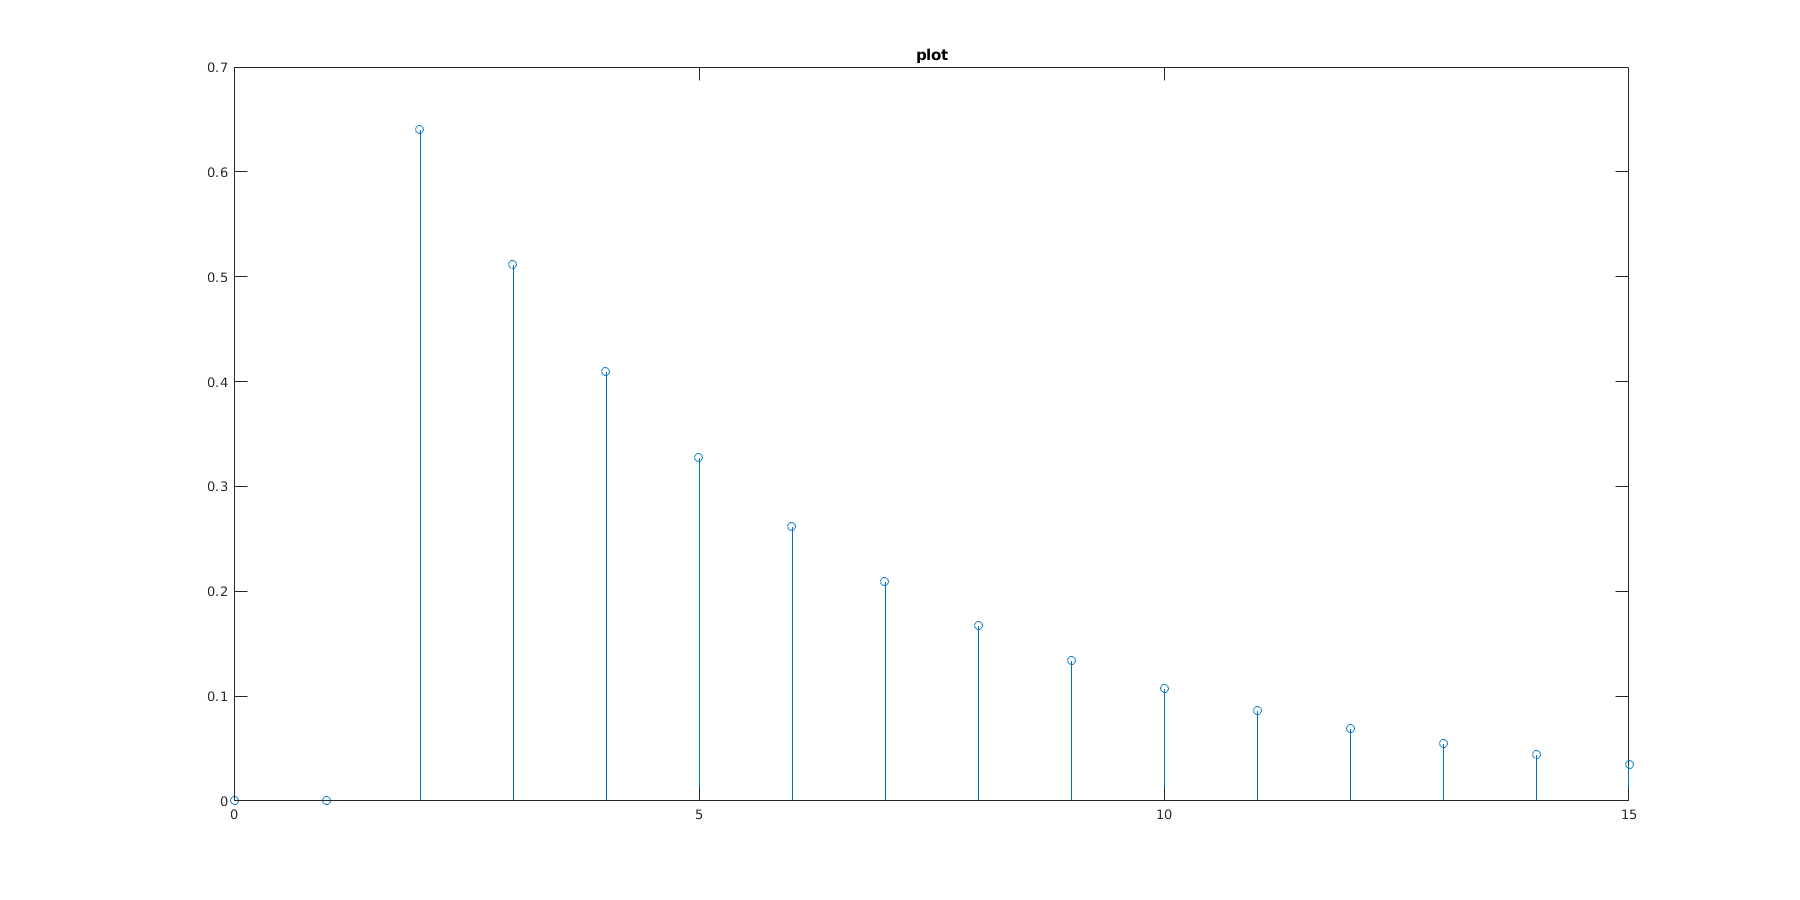

t2 = 0:15;
step_fig(t2,subs(x2,t2),"plot")

H = simplify(ztrans(x2))

$$H = \frac{16}{5\,z\,\left(5\,z-4\right)}$$

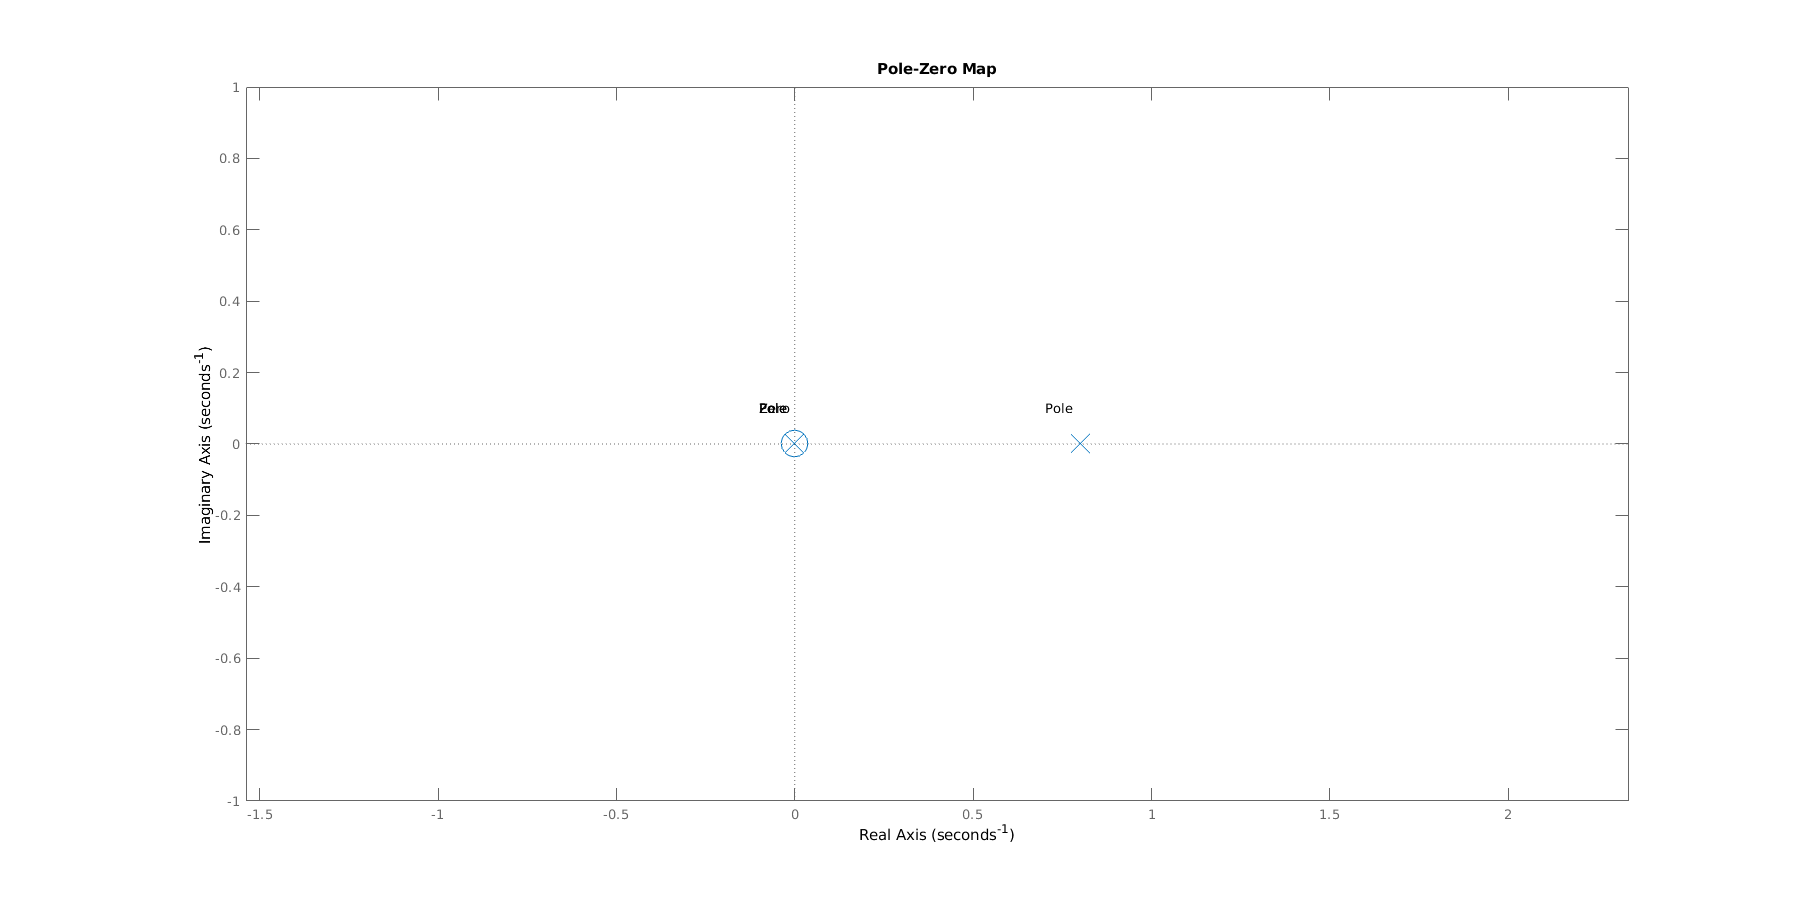

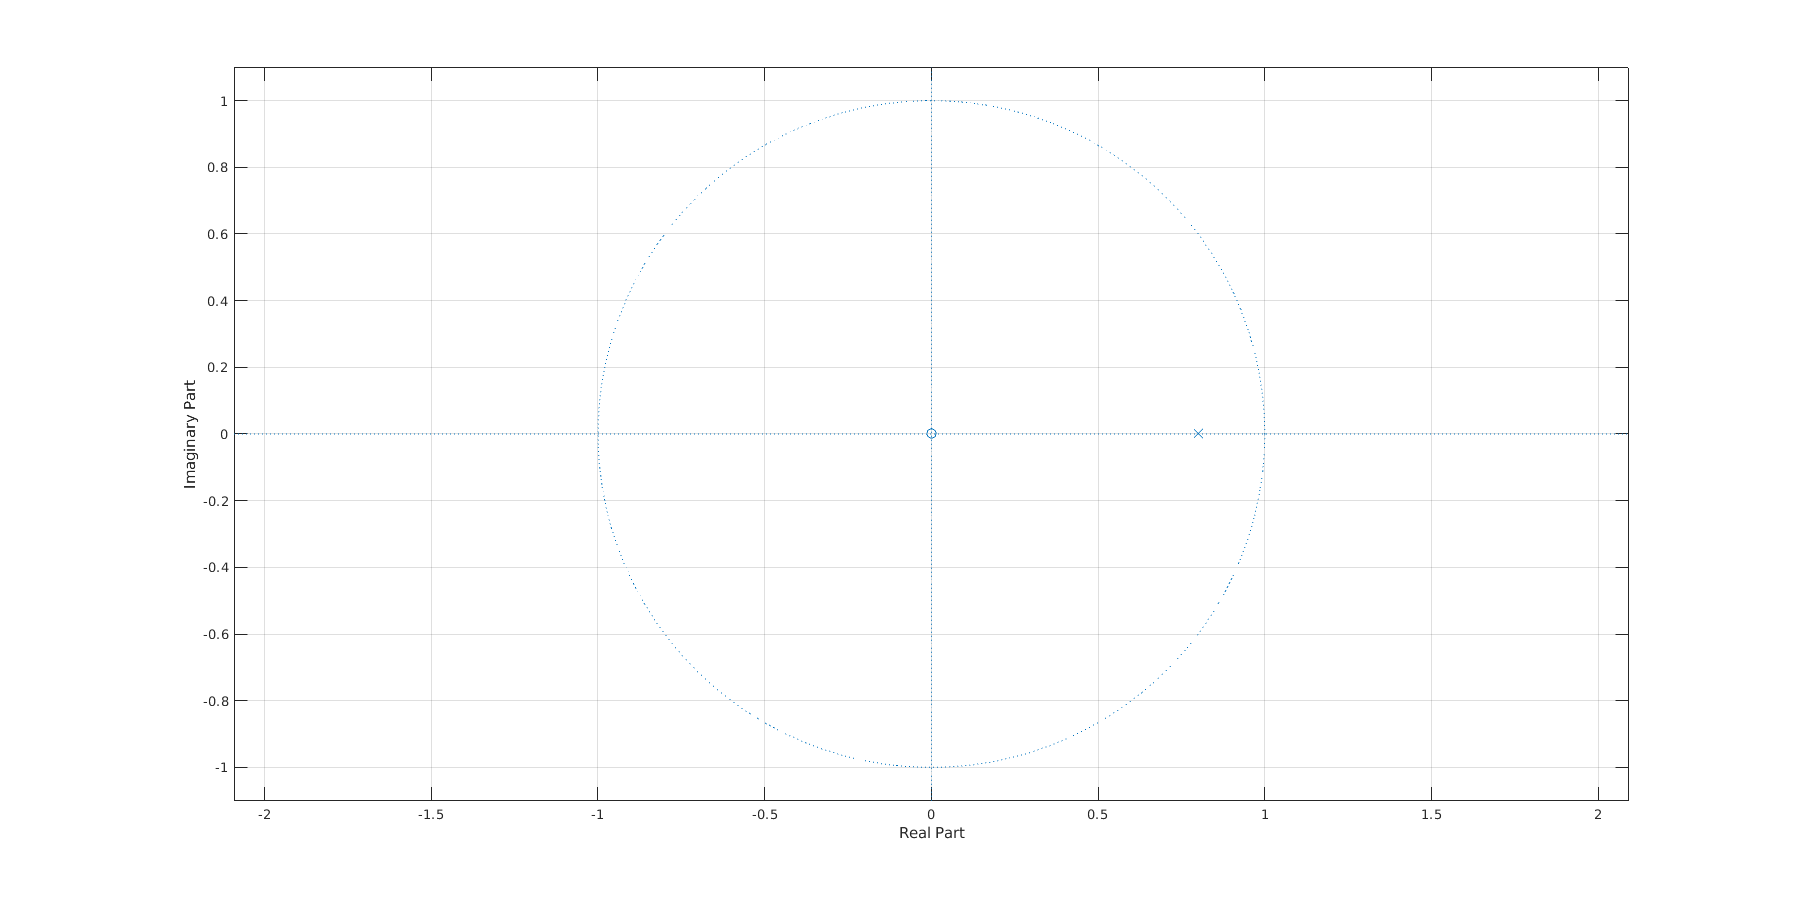

plot_z_plan([5/4,0],[5/4,-1,0,0])


x3 = 2^n* cos(0.4*pi*n) * heaviside(n)

$$x3 = 2^{n}\,\cos\left(\frac{2\,\pi \,n}{5}\right)\,\mathrm{heaviside}\left(n\right)$$

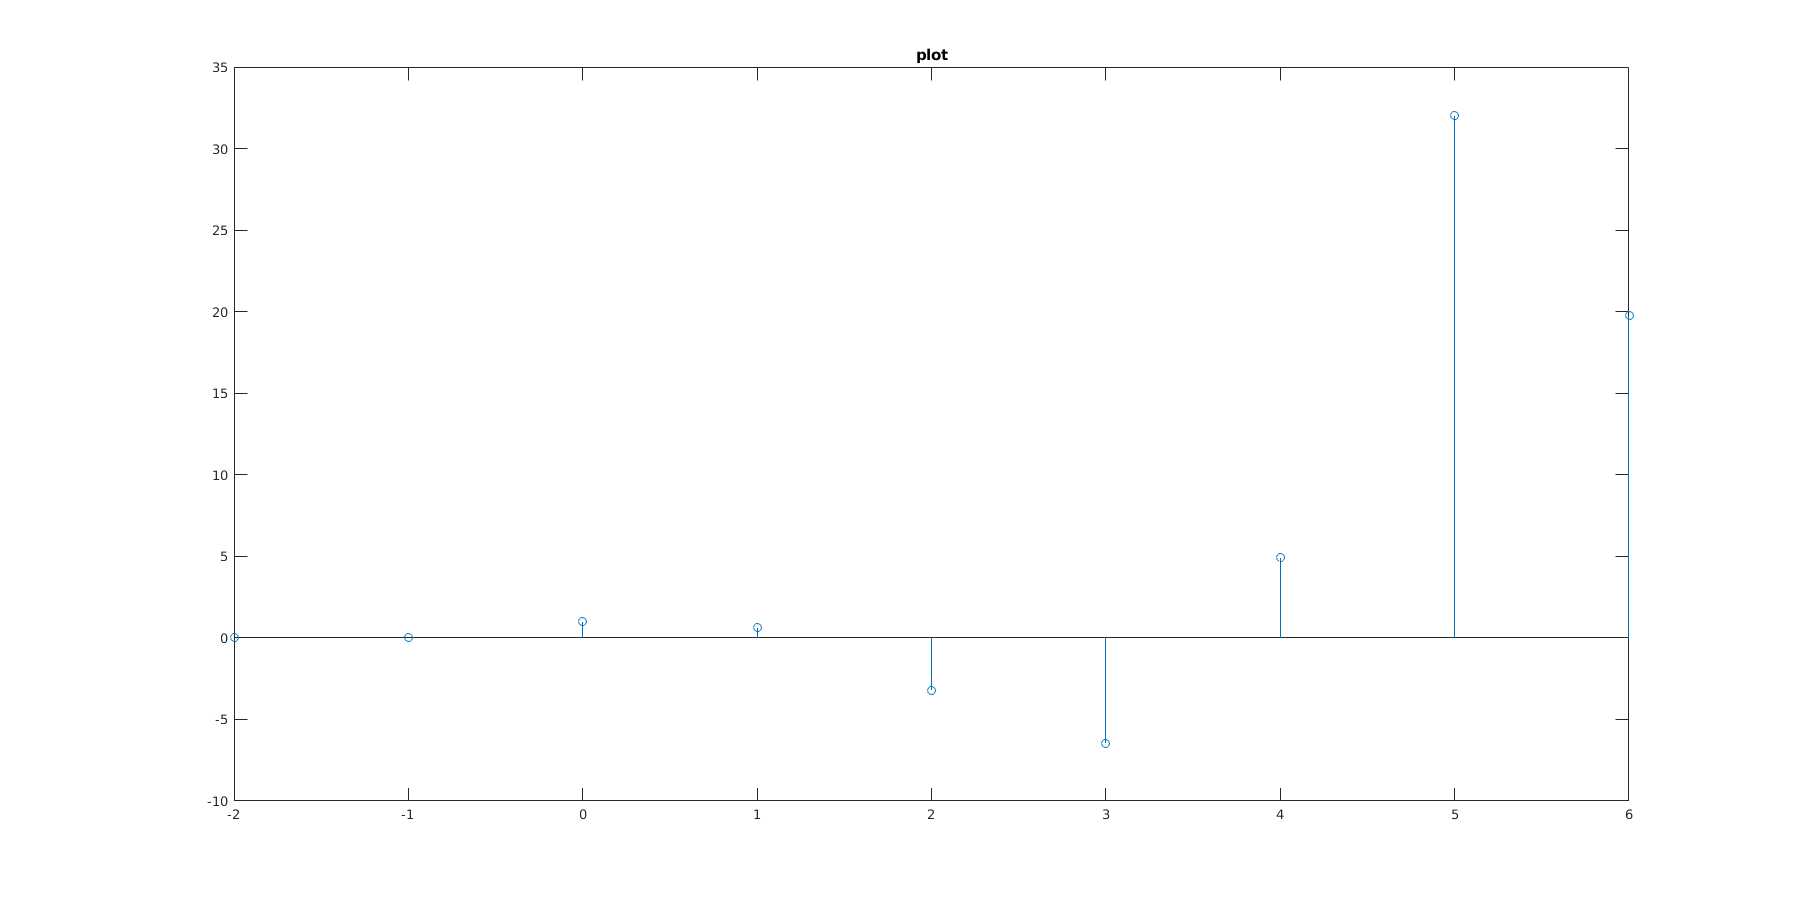

t3 = -2:6;
step_fig(t3,subs(x3,t3),"plot")

H = ztrans(x3)

$$H = \frac{2\,\mathrm{ztrans}\left(\cos\left(\frac{2\,\pi \,\left(n+1\right)}{5}\right),n,\frac{z}{2}\right)}{z}+1$$

H = (z-2*cos(0.4*pi))/(z^2-4*cos(0.4*pi)*z + 4)

$$H = \frac{z-\frac{347922205179541}{562949953421312}}{z^{2}-\frac{347922205179541\,z}{281474976710656}+4}$$

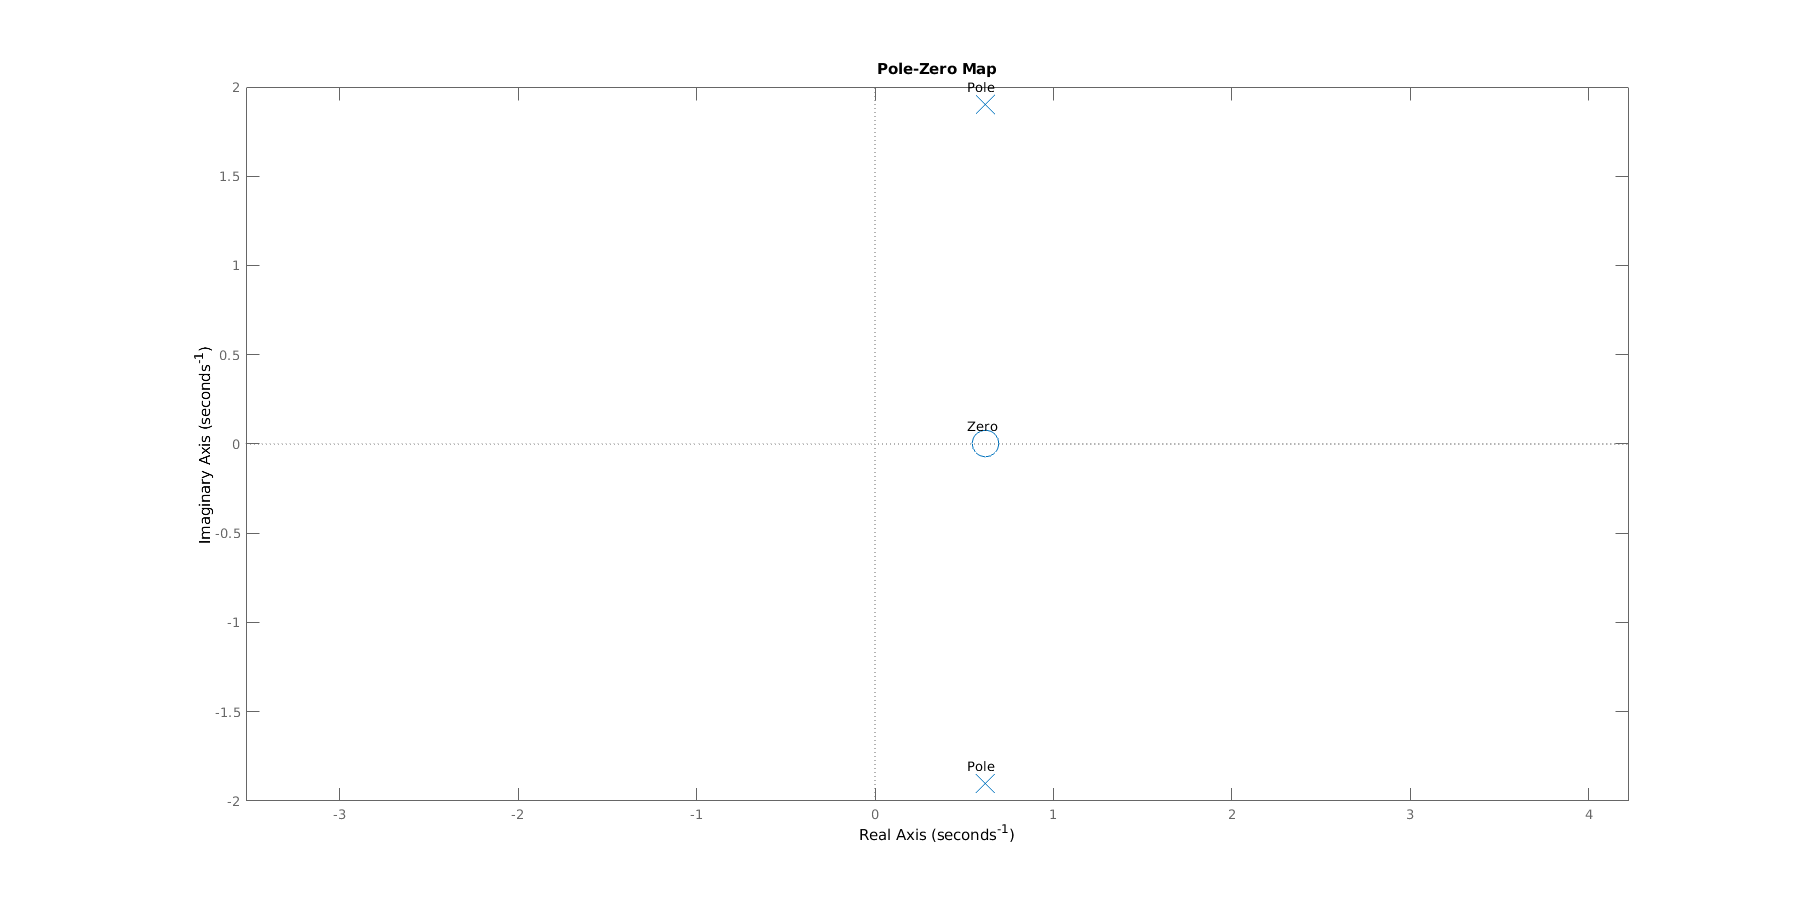

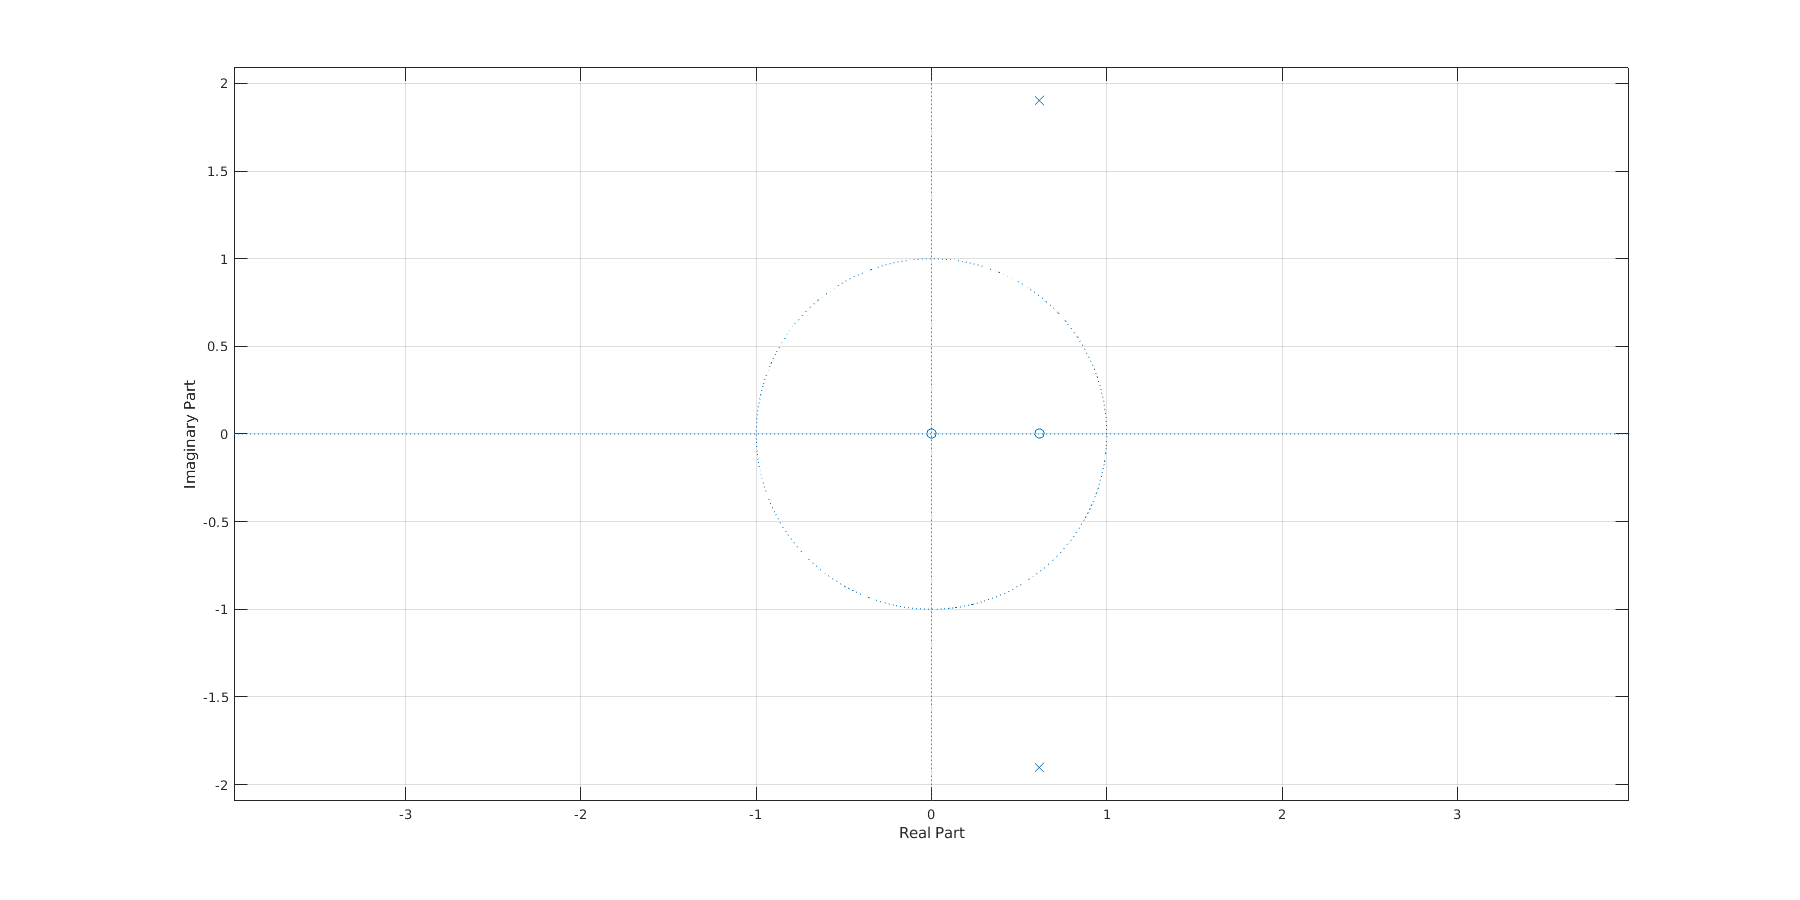

plot_z_plan([1,-2*cos(0.4*pi)],[1,-4*cos(0.4*pi),4])

%[r,p,k] = residuez([1,-2*cos(0.4*pi)],[1,-4*cos(0.4*pi),4])

part two

a

syms z
num1 = [1,-1,0];
dom1 = [1,-1,0.5];
H1 = (z^2-z)/(z^2 - z + 0.5)

$$H1 = -\frac{z-z^{2}}{z^{2}-z+\frac{1}{2}}$$

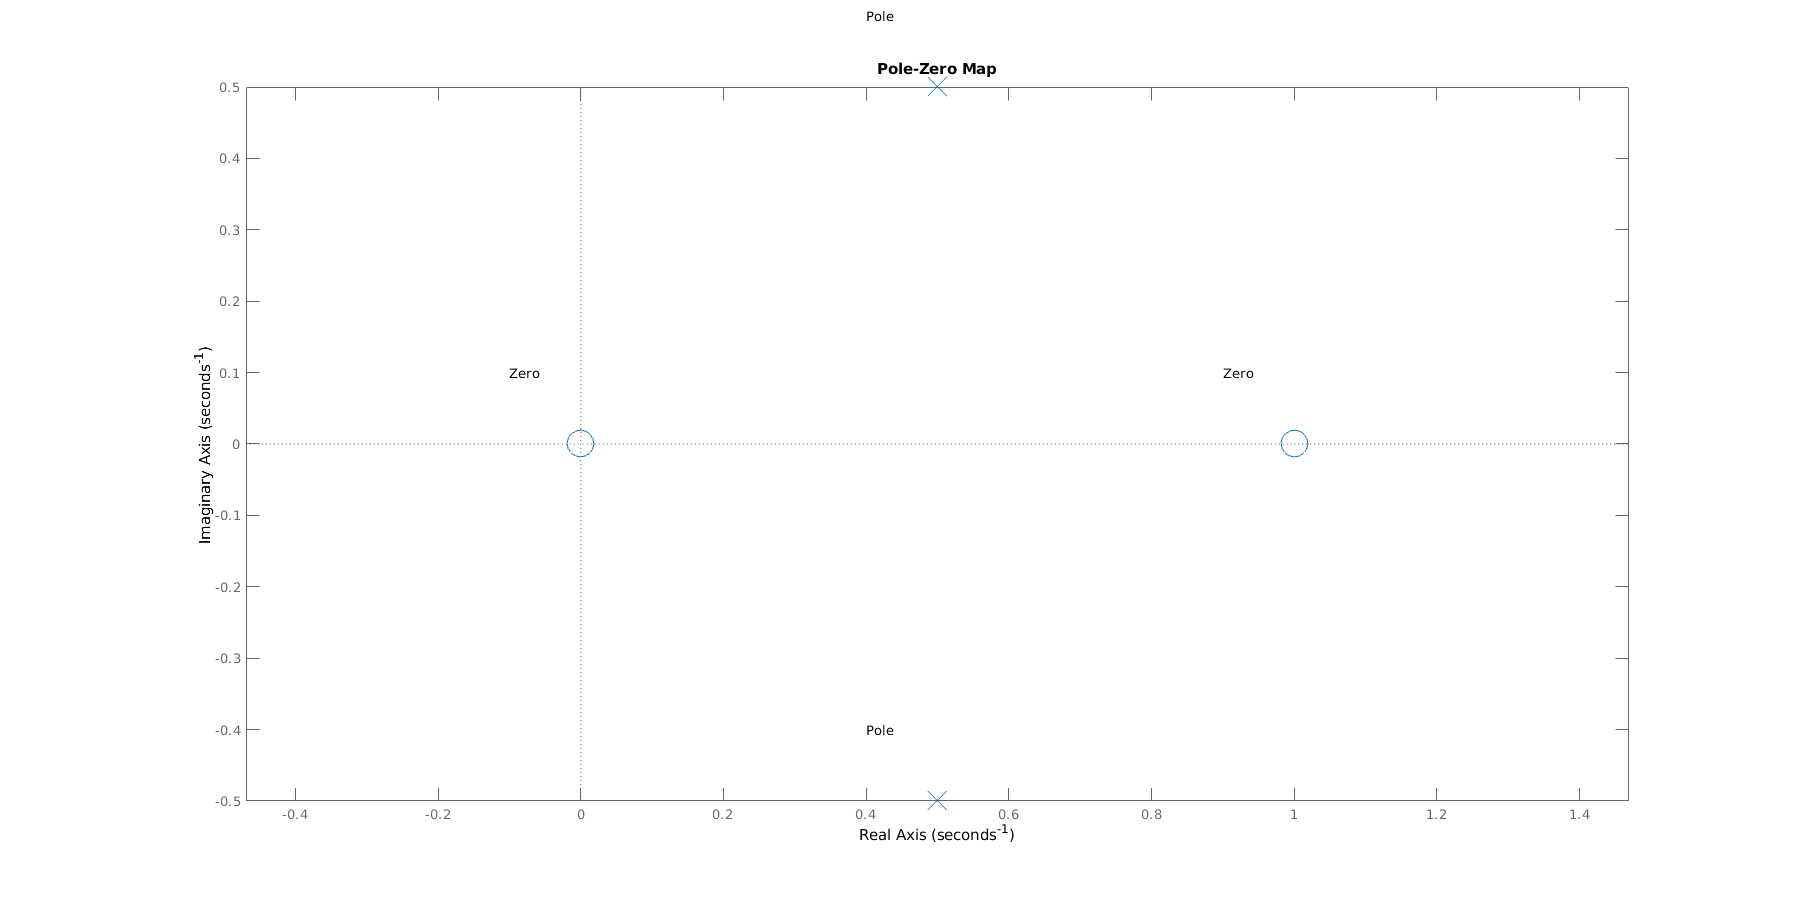

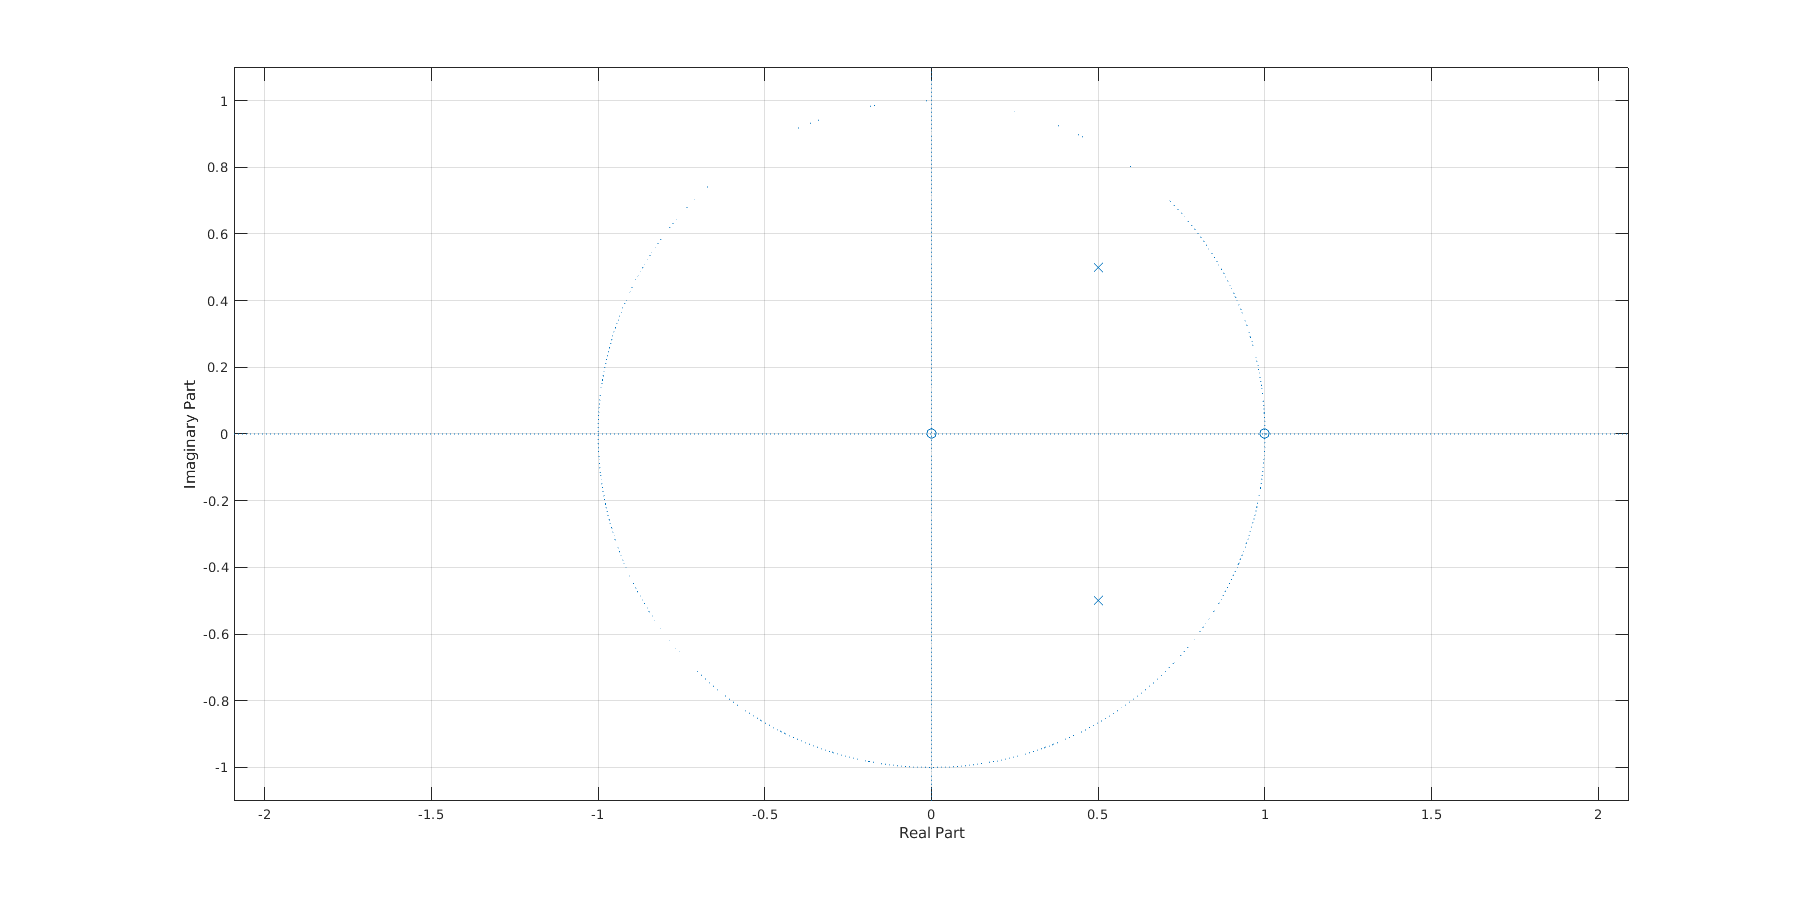

plot_z_plan(num1,dom1)

num2 = [1,0];
dom2 = [2, - sqrt(3),0.5];
H2 = (z)/(z^2 - sqrt(3)*z + 0.5)

$$H2 = \frac{z}{z^{2}-\sqrt{3}\,z+\frac{1}{2}}$$

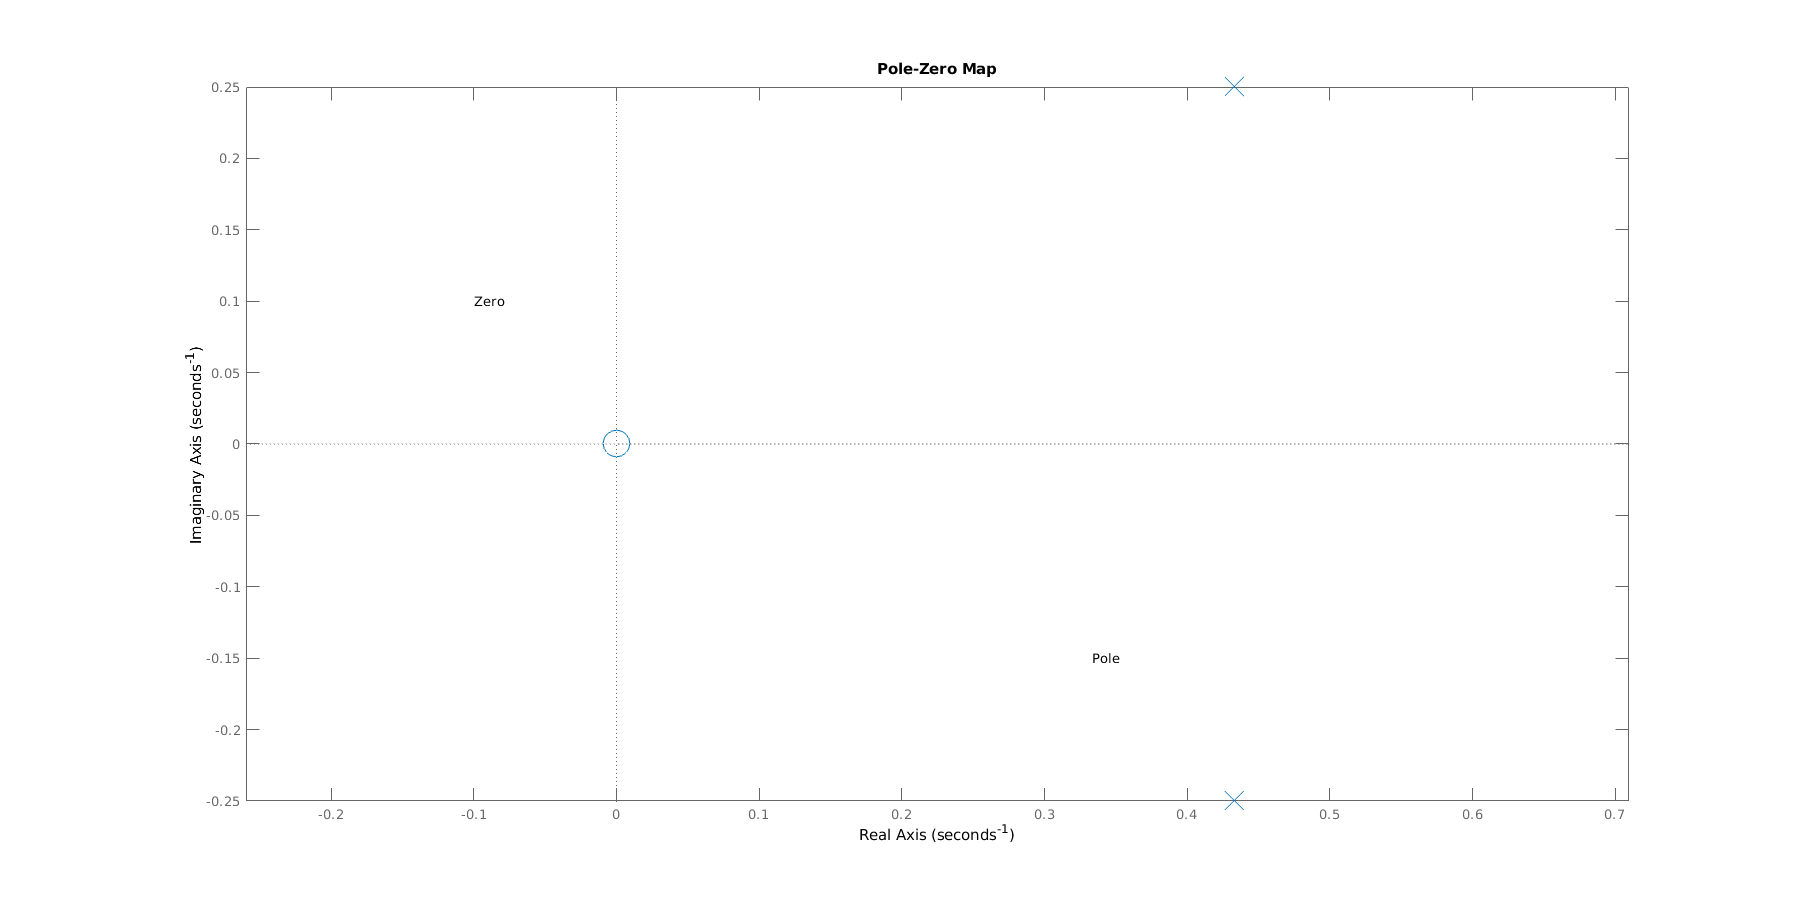

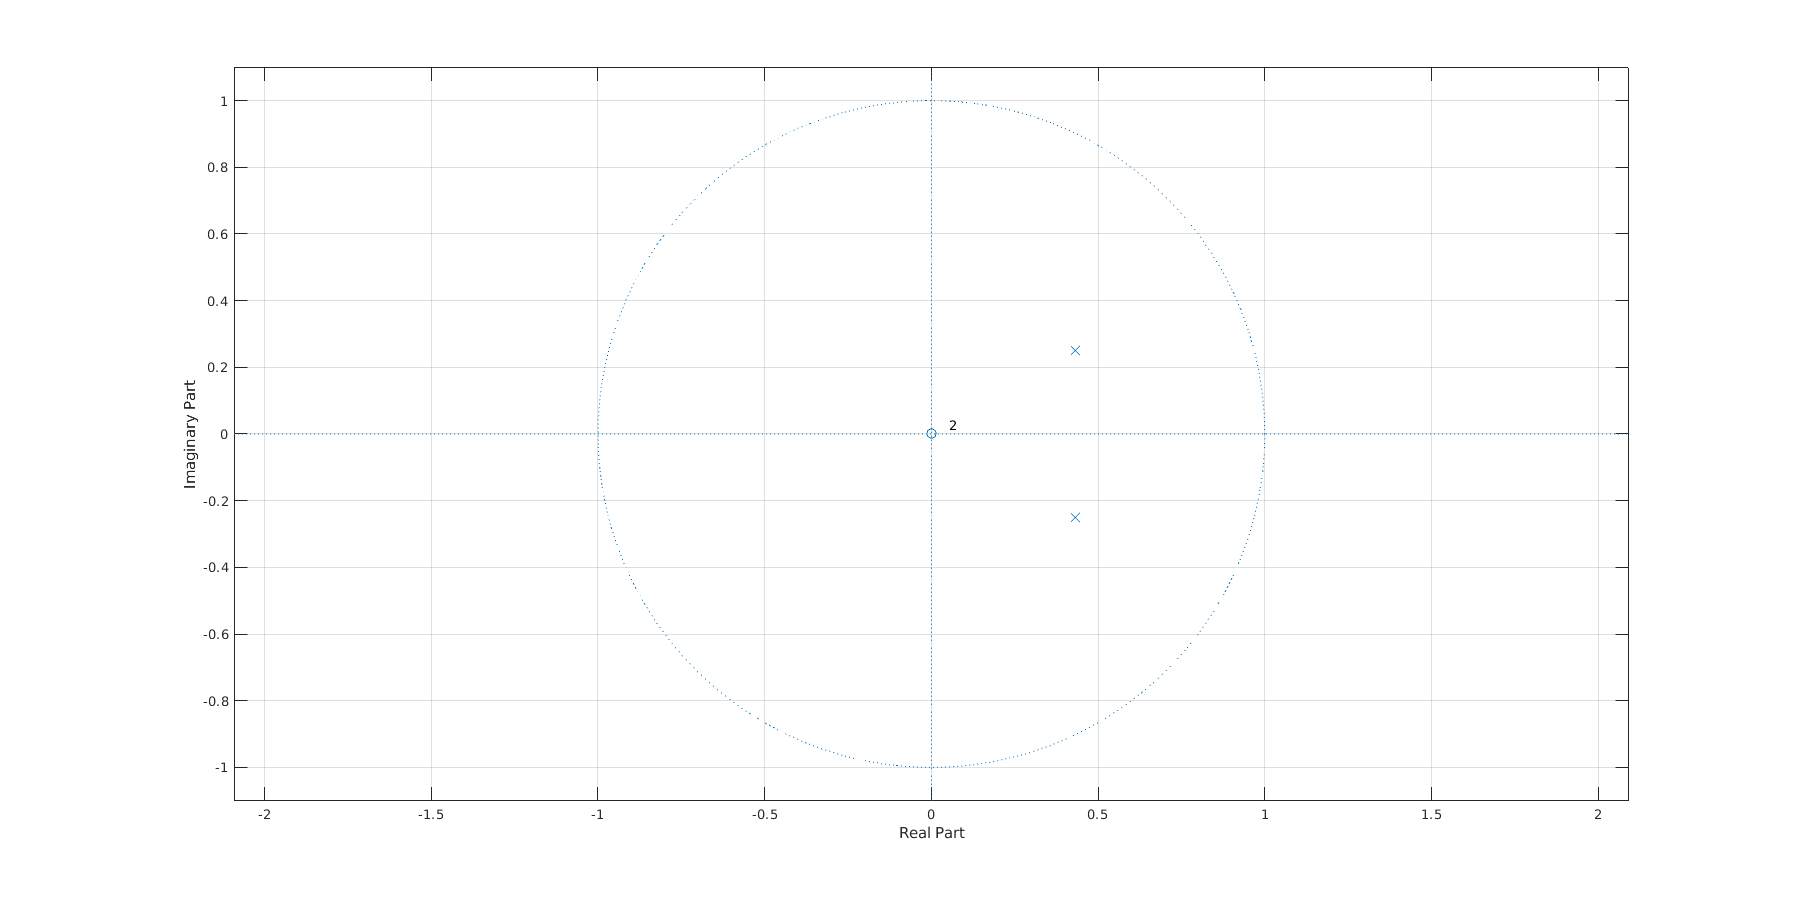

plot_z_plan(num2,dom2)

b

[r1,p1,k1] = residuez(num1,dom1)

r1 =    0.5000 + 0.5000i
   0.5000 - 0.5000i


p1 =    0.5000 + 0.5000i
   0.5000 - 0.5000i



k1 =

     []



[r2,p2,k2] = residuez(num2,dom2)

r2 =    0.2500 - 0.4330i
   0.2500 + 0.4330i


p2 =    0.4330 + 0.2500i
   0.4330 - 0.2500i



k2 =

     []



c

oldparam = sympref('HeavisideAtOrigin',1);
h1 = simplify(iztrans(H1))

$$h1 = \frac{{\left(-1\right)}^{n}\,\left({\left(-1-\mathrm{i}\right)}^{n}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right)+{\left(-1+\mathrm{i}\right)}^{n}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right)\right)}{2^{n}}$$

h2 = simplify(iztrans(H2))

$$h2 = \frac{{\left(-1\right)}^{n}\,2^{1-n}\,\sqrt{3}\,{\left(1-\sqrt{3}\right)}^{n-1}}{3}-\frac{{\left(-1\right)}^{n}\,2^{1-n}\,\sqrt{3}\,{\left(-\sqrt{3}-1\right)}^{n-1}}{3}+\frac{2\,{\left(-1\right)}^{n}\,\sqrt{3}\,\cos\left(n\,\left(\pi -\mathrm{acos}\left(\frac{\sqrt{2}\,\sqrt{3}}{2}\right)\right)\right)}{3\,2^{n/2}}$$